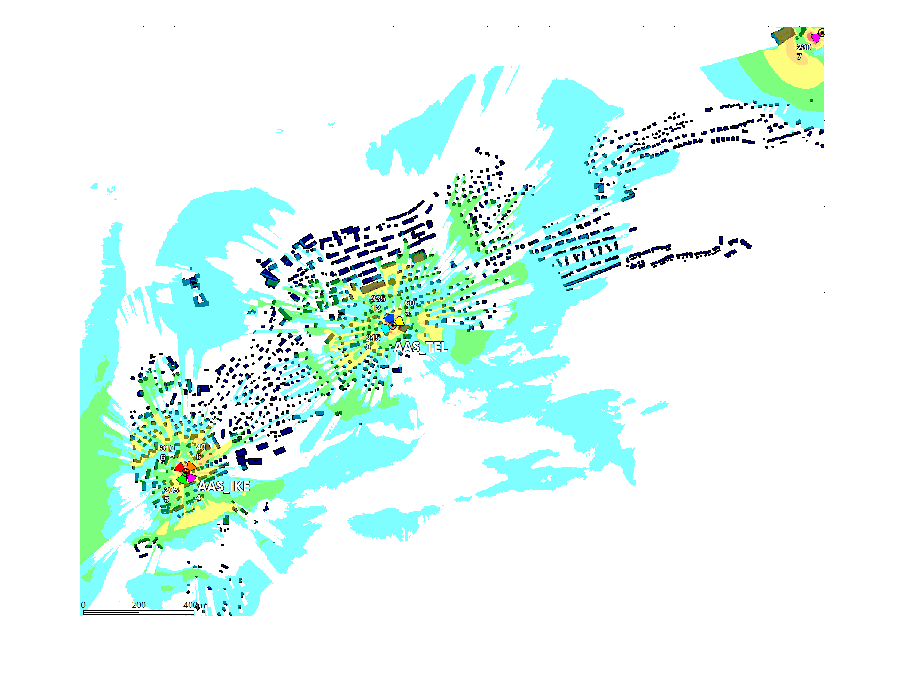

mc = imread('aas n78 sig cropped.png');
imshow(mc);

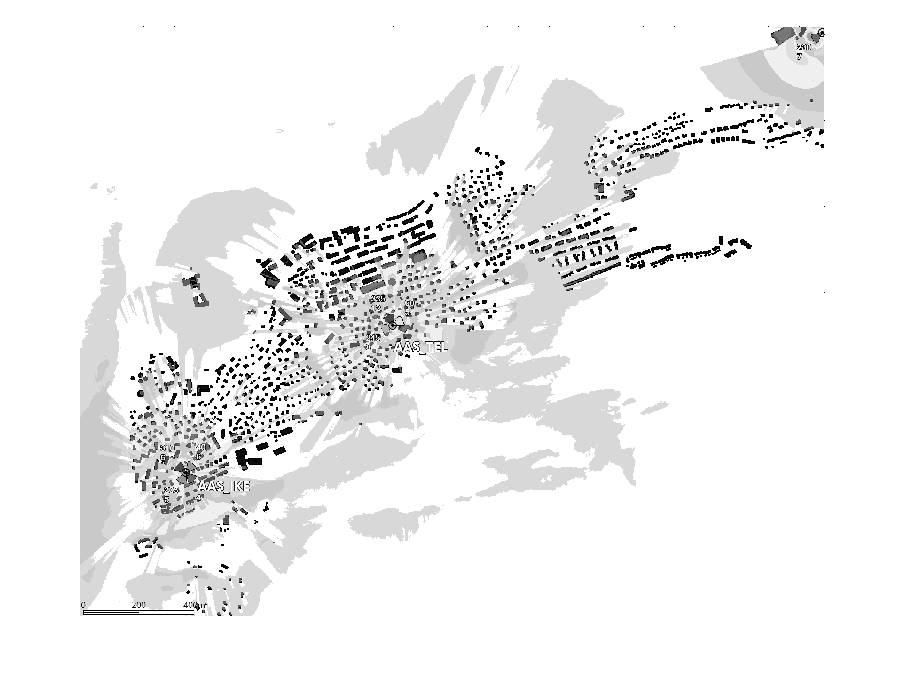

Igr = rgb2gray(mc);
imshow(Igr, []);

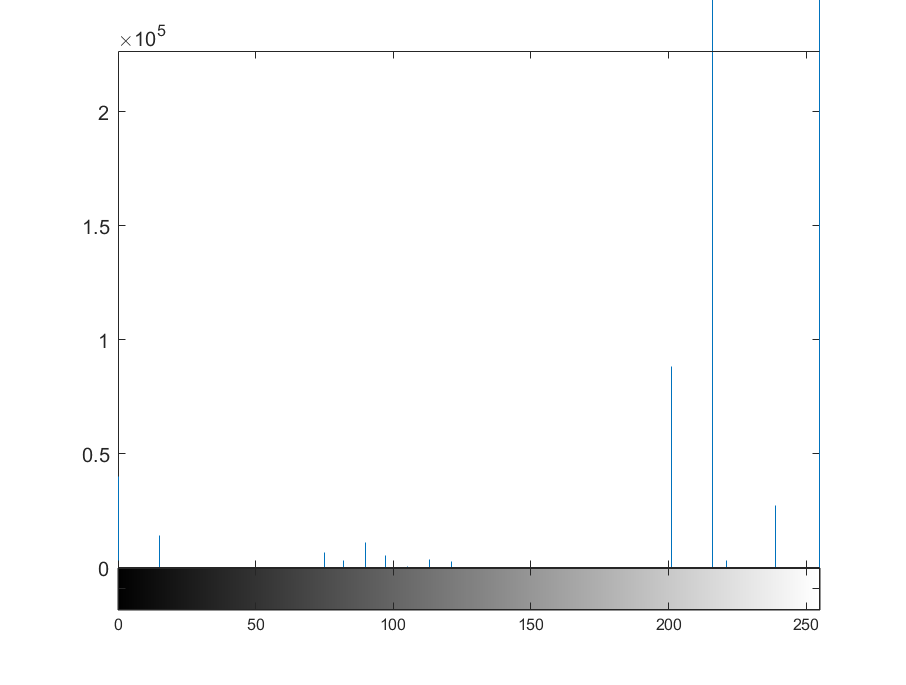

imhist(Igr);


thisIntensity = impixel(Igr, 50, 50);
thisIntensity

thisIntensity =    255   255   255


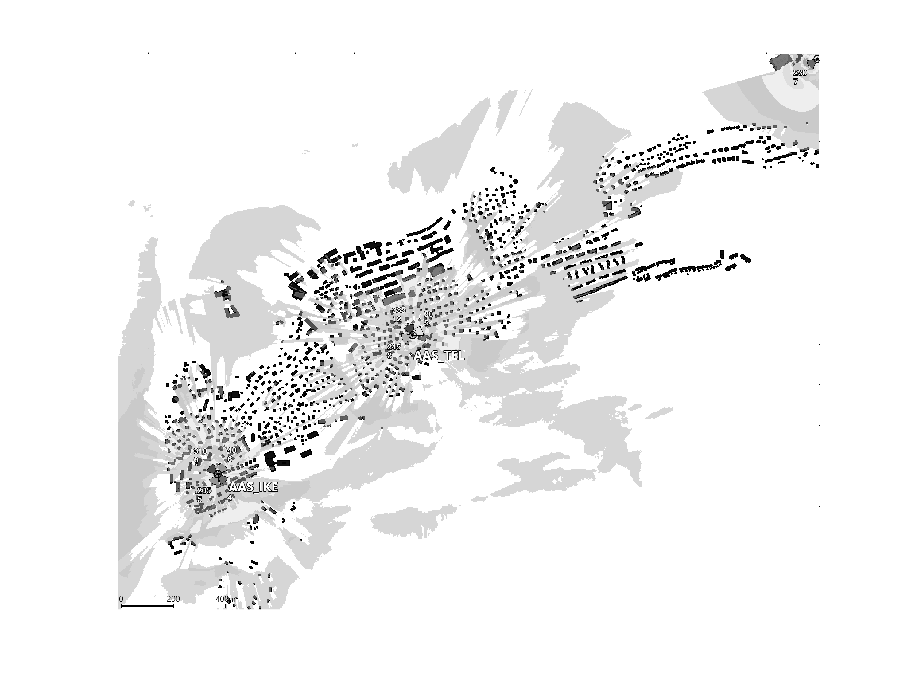

[X, map] = gray2ind(Igr, 64);
imshow(X, map);

indices = find(abs(X)>49);
X(indices) = 255;

indices2 = find(abs(X)<49);
X(indices2) = 0;
X

X = 1255×1585 uint8 matrix
   255   255     0   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255     0   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255     0   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   2

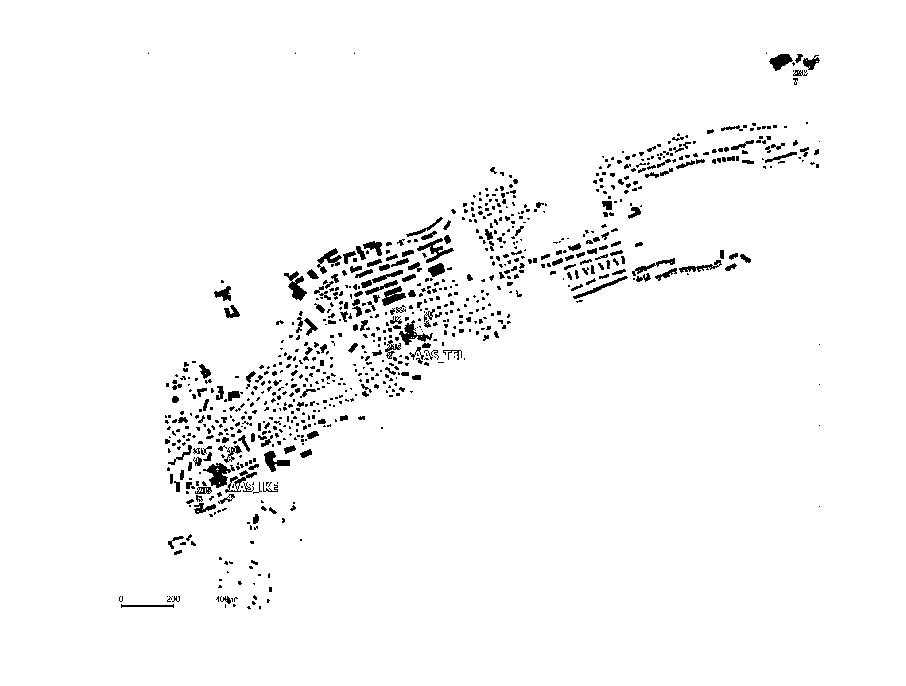

imshow(X, map);

X(1,3);
[row,col] = find(abs(X)<1);
[row,col] 

ans =            1           3
           2           3
           3           3
        1231           3
        1232           3
        1233           3
        1234           3
        1228           4
        1229           4
        1230           4


rgbColor = impixel(mc, col, row)

rgbColor =      0     0     0
     0     0     0
     0     0     0
   126   219   143
   126   219   143
   126   219   143
   126   219   143
   108   143    57
    71    57     0
    50     0     0


Ar = reshape(rgbColor, [],3)

Ar =      0     0     0
     0     0     0
     0     0     0
   126   219   143
   126   219   143
   126   219   143
   126   219   143
   108   143    57
    71    57     0
    50     0     0


[Aru,~,ix] = unique(Ar,'rows','stable')

Aru =      0     0     0
   126   219   143
   108   143    57
    71    57     0
    50     0     0
    28     0     0
    90   102     0
     0     0   102
     0   102   181
    28   143   219


ix =      1
     1
     1
     2
     2
     2
     2
     3
     4
     5


Count = accumarray(ix,1);
Out = [Aru, Count]

Out =            0           0           0       40106
         126         219         143          28
         108         143          57          37
          71          57           0          29
          50           0           0          42
          28           0           0          29
          90         102           0          19
           0           0         102         147
           0         102         181          33
          28         143         219          12


Out = sortrows(Out,4,'descend')

Out =            0           0           0       40106
           0           0         128       14000
           0         128         128       11142
           0         128           0        6815
           0         128         191        5334
         128         128           0        3643
           0         128          63        3480
         128         128          63        2840
         255           0         255         475
         127          97           0         384


sum(Out(2:9,4));
Out = Out(2:11,:)

Out =            0           0         128       14000
           0         128         128       11142
           0         128           0        6815
           0         128         191        5334
         128         128           0        3643
           0         128          63        3480
         128         128          63        2840
         255           0         255         475
         127          97           0         384
         254         126         126         377


OutC4 = Out(:,4)

OutC4 =        14000
       11142
        6815
        5334
        3643
        3480
        2840
         475
         384
         377


y = zeros(1,7);
for i = 1:max(size(y))
    for k = 1:10
        if i == 1
            if Out(k,1) == 128 && Out(k,2) == 0
                y(1) = Out(k,4)+y(1);
            end
        end

        if i == 2
            if Out(k,1) == 127 && (Out(k,2) == 84 || Out(k,2) == 63) || Out(k,2) == 97 || (Out(k,1) == 127 && (Out(k,2) == 84 || Out(k,2) == 63 || Out(k,2) == 94) && Out(k,3) == 63)
                y(2) = Out(k,4)+y(2);
            end
        end

        if i == 3
            if (Out(k,1) == 128 || Out(k,1) == 127) && (Out(k,2) == 128 || Out(k,2) == 127)
                y(3) = Out(k,4)+y(3);
            end
        end

        if i == 4
            if Out(k,1) == 0 && Out(k,2) == 128 && (Out(k,3) == 0 || Out(k,3) == 63)
                y(4) = Out(k,4)+y(4);
            end
        end

        if i == 5
            if Out(k,2) == 128 && Out(k,3) == 128
                y(5) = Out(k,4)+y(5);
            end

        end

        if i == 6
            if Out(k,2) == 128 && Out(k,3) == 191
                y(6) = Out(k,4)+y(6);
            end
        end

        if i == 7
            if Out(k,3) == 128 && Out(k,2) == 0
                y(7) = Out(k,4)+y(7);
            end
        end

    end
end
y1 = y

y1 =            0         384        6483       10295       11142        5334       14000


size(y1)

ans =      1     7


sum(y1)

ans = 47638


x = [-70 -80 -90 -100 -110 -120 -130];
y = y./sum(y)

y =          0    0.0081    0.1361    0.2161    0.2339    0.1120    0.2939


y1 = y;
sum(y)

ans = 1

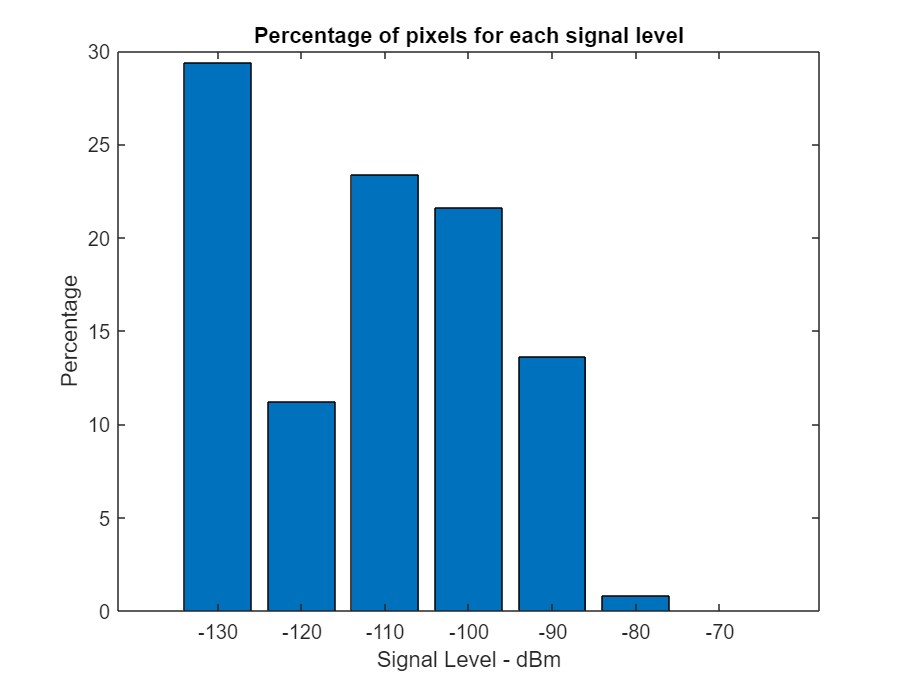

bar(x,y*100)
xlabel('Signal Level - dBm')
ylabel('Percentage')
title('Percentage of pixels for each signal level')

PenLoss = 15;
AntGain = 5;
Ypen = zeros(1,7);

if AntGain > 0
TotalGain = PenLoss + AntGain;
else
TotalGain = PenLoss;
end

for i = 1:7

end